r = zeros(256,3);
g = zeros(256,3);
b = zeros(256,3);

r(:,1) = linspace(0,1,256);
g(:,2) = linspace(0,1,256);
b(:,3) = linspace(0,1,256);

map = [r(:,1) g(:,2) b(:,3)];
% assignment section
[a1,a2,a3] = ilusion1(100,130,160,120);

% gs -> green square
% (89,169)
a1gs = a1/256;
a1gs(:,:,1) = 0;
a1gs(:,:,2) = 0;
a1gs(89:169,89:169,2) = 120;
a1gs(89:169,89:169,3) = 0;
%imshow(a1gs,g+b)

a2gs = a2/256;
a2gs(:,:,1) = 0;
a2gs(:,:,2) = 0;
a2gs(89:169,89:169,2) = 120;
a2gs(89:169,89:169,3) = 0;
%imshow(a2gs,g+b)

a3gs = a3/256;
a3gs(:,:,1) = 0;
a3gs(:,:,2) = 0;
a3gs(89:169,89:169,2) = 120;
a3gs(89:169,89:169,3) = 0;
%imshow(a3gs,g+b)
% -------------------------
a1gsr = a1/256;
a1gsr(:,:,3) = 0;
a1gsr(:,:,2) = 0;
a1gsr(89:169,89:169,2) = 120;
a1gsr(89:169,89:169,3) = 0;
%imshow(a1gsr,r+g)

a2gsr = a2/256;
a2gsr(:,:,3) = 0;
a2gsr(:,:,2) = 0;
a2gsr(89:169,89:169,2) = 120;
a2gsr(89:169,89:169,3) = 0;
%imshow(a2gsr,r+g)

a3gsr = a3/256;
a3gsr(:,:,3) = 0;
a3gsr(:,:,2) = 0;
a3gsr(89:169,89:169,2) = 120;
a3gsr(89:169,89:169,3) = 0;
%imshow(a3gsr,r+g)

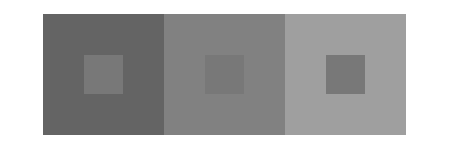

A = horzcat(a1,a2,a3);

imshow(A/256,map)

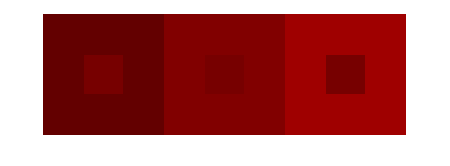

imshow(A(:,:,1),r)

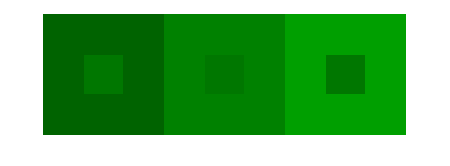

imshow(A(:,:,2),g)

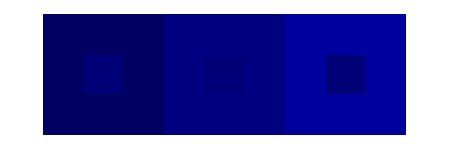

imshow(A(:,:,3),b)

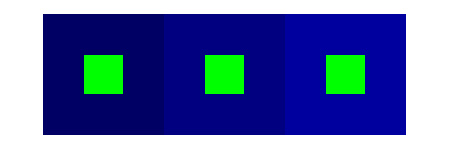

imshow(horzcat(a1gs,a2gs,a3gs),g+b)

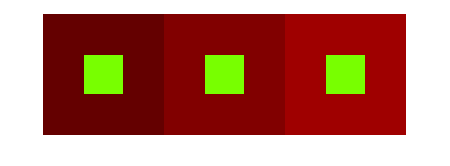

imshow(horzcat(a1gsr,a2gsr,a3gsr),r+g)

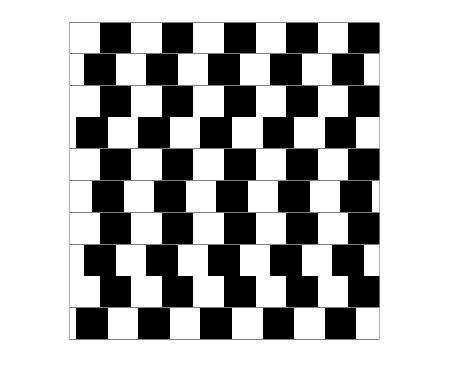

% ilusion 2
ilu = ilusion2();
imshow(ilu)

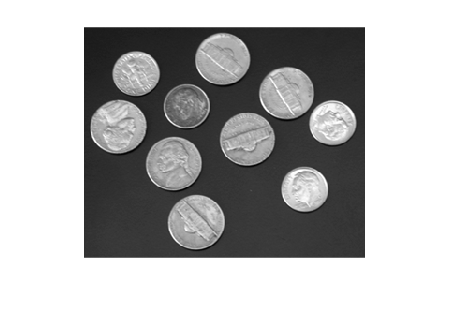

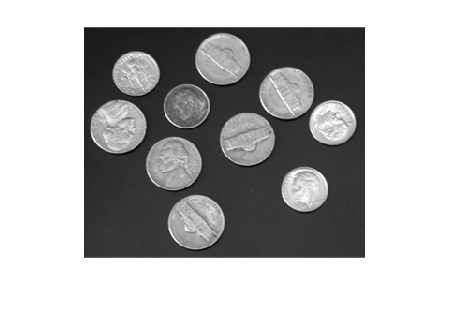

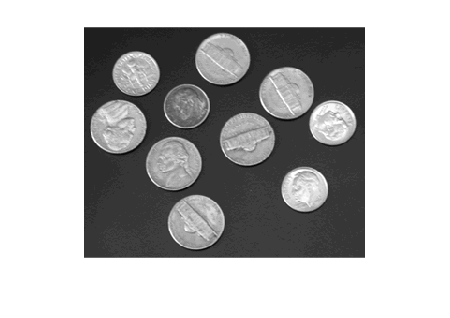

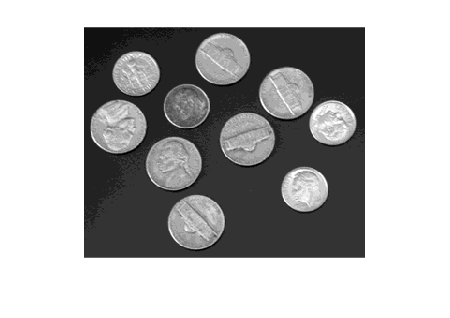

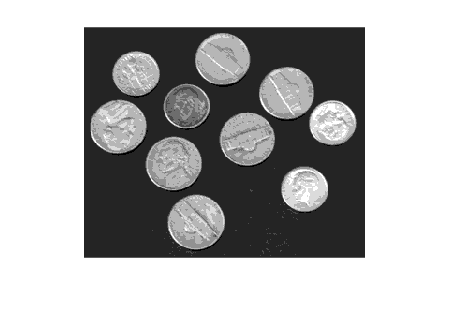

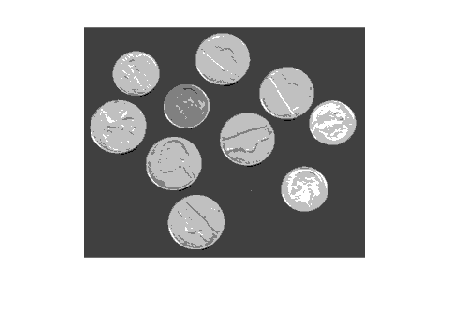

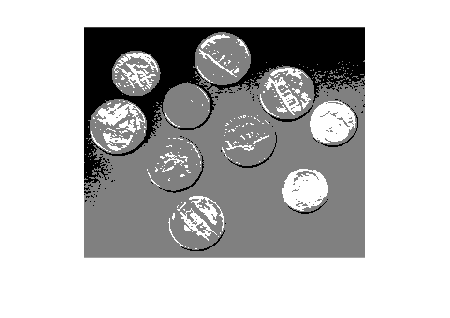

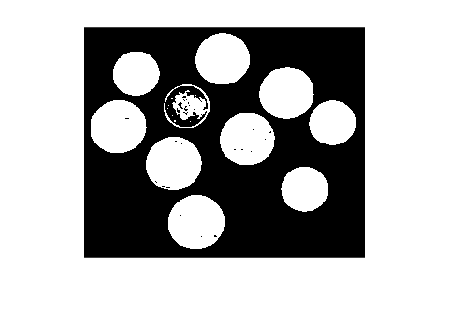

[I] = imread("coins.png");
cuantificar(I,8);

img = [
    "cuant_1.png"
    "cuant_2.png"
    "cuant_3.png"
    "cuant_4.png"
    "cuant_5.png"
    "cuant_6.png"
    "cuant_7.png"
    "cuant_8.png"
];

%imshow(imtile(img,[],"BackgroundColor","k","GridSize",[2 4]))

function [] = cuantificar(I,N)
   for i=1:N
        aux = (I)/(2^(i)- 1);
        figure
        imshow(aux,[])
   end
end

function [uno,dos, tre] = ilusion1(a1,a2,a3,b)

    uno = ones(257,257,3)*a1;
    dos = ones(257,257,3)*a2;
    tre = ones(257,257,3)*a3;
    
    centro = 129;
    tamano = 40;
    
    uno(centro-tamano:centro+tamano,centro-tamano:centro+tamano,:) = b;
    dos(centro-tamano:centro+tamano,centro-tamano:centro+tamano,:) = b;
    tre(centro-tamano:centro+tamano,centro-tamano:centro+tamano,:) = b;
end

function [illusion] = ilusion2()
    illusion = ones(410,400);
    illusion(1,:)=0.5;
    for i=1:10
        illusion(i*41,:) = 0.5;
    end

    illusion(1:410,1) = 0.5;
    illusion(1:410,400) = 0.5;
    
    range = [20 60;100 140;180 220;260 300;340 380];
    for i=1:9
        for j=1:5
            if mod(i,2) == 0
                illusion(2+(41*i-1):41+(41*i-1),(range(j,1)+20):(range(j,2)+20)) = 0;
            elseif mod(i,3)==0
                illusion(2+(41*i-1):41+(41*i-1),(range(j,1)-10):(range(j,2)-10)) = 0;
            elseif mod(i,5)==0
                illusion(2+(41*i-1):41+(41*i-1),(range(j,1)+10):(range(j,2)+10)) = 0;
            else
                illusion(2+(41*i-1):41+(41*i-1),range(j,1):range(j,2)) = 0;
            end
        end
    end
    
    for i=1:5
        illusion(2:40,(range(i,1))+20:(range(i,2))+20)=0;
    end
end

function [uno,dos,tre] = ilusion3(a1,a2,a3,b)

    uno = ones(257,257)*a1;
    dos = ones(257,257)*a2;
    tre = ones(257,257)*a3;
    
    centro = 129;
    tamano = 40;
    
    uno(centro-tamano:centro+tamano,centro-tamano:centro+tamano,:) = b;
    dos(centro-tamano:centro+tamano,centro-tamano:centro+tamano,:) = b;
    tre(centro-tamano:centro+tamano,centro-tamano:centro+tamano,:) = b;
end